## Example: Null space and Left null space

%Numeric Matlab
A=[1 0 1;5 4 9;2 4 6];
NA=null(A); %By definition, solutions of the homogenous system Ax=0
disp("A norm: " + norm(A));

A norm: 13.3048


NAT=null(A')

NAT =     0.9045
   -0.3015
    0.3015



%Symbolic Matlab
S=sym([1 0 1;5 4 9;2 4 6]);
NS=null(S);
disp("Null space (symbolic):");

Null space (symbolic):


NS

$$NS = \left(\begin{array}{c} -1\\ -1\\ 1 \end{array}\right)$$

disp("----------------------");

----------------------


disp("Norm null space: ");

Norm null space: 


disp(norm(NS))

$$\sqrt{3}$$

disp("----------------------");

----------------------


disp("Left null space (symbolic):");

Left null space (symbolic):


NST=null(S')

$$NST = \left(\begin{array}{c} 3\\ -1\\ 1 \end{array}\right)$$

disp("-----------------------");

-----------------------


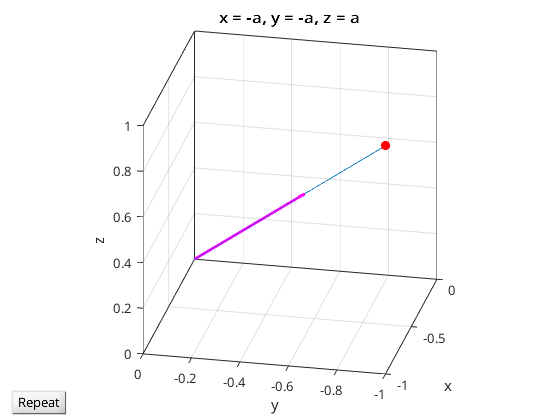

% Visualize the Null space and the left null space
A=[1 0 1;5 4 9;2 4 6];
NA=null(A);

syms a real; r=a*NS;
ezplot3(r(1),r(2),r(3),[0 1],'animate');
axis tight; axis equal; hold on; box on;
h=quiver3(0,0,0,NA(1),NA(2),NA(3),1);
set(h,'Color','m','LineWidth',2);
view(-78,23);

## Example: Column Space and Row Space

% Numeric
disp("Example: Column Space and Row Space"); 

Example: Column Space and Row Space


disp("Numeric Matlab")

Numeric Matlab


A=[1 0 1;5 4 9;2 4 6];
disp("Rank of matrix A: " + rank(A));

Rank of matrix A: 2


RA=orth(A); % We use the orthonormal function to get the Column Space
disp(RA);

   -0.0915    0.4165
   -0.8279    0.4729
   -0.5533   -0.7765



RAT=orth(A');
disp(RAT);

   -0.4012    0.7111
   -0.4153   -0.7030
   -0.8165    0.0081




RA'*RA %Orthonormal columns, the result is the eye matrix

ans =     1.0000    0.0000
    0.0000    1.0000


norm(RA(:,1)) %Norm is one

ans = 1.0000

norm(RA(:,1))
disp(rref(A))

%Symbolic
disp("Example: Column Space and Row Space - Symbolic Matlab")

Example: Column Space and Row Space - Symbolic Matlab


S=sym([1 0 1;5 4 9;2 4 6]);
RS=colspace(S) % Calculate the row space?

$$RS = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -3 & 1 \end{array}\right)$$

RST=colspace(S')

$$RST = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 1 & 1 \end{array}\right)$$

%The orth function can also be applied to symolic matrix
S=sym([1 0 1;5 4 9;2 4 6]);
RS1=simplify(orth(S))
RS1'*RS1 %Identical matrix

## Null Space and Row Space

disp("Null space and row space")

Null space and row space


A=[1 0 1;5 4 9;2 4 6]; %Define my matrix
S=rref(A); % Get the reduced echelon form
S %First and second columns are linearly independent

S =      1     0     1
     0     1     1
     0     0     0


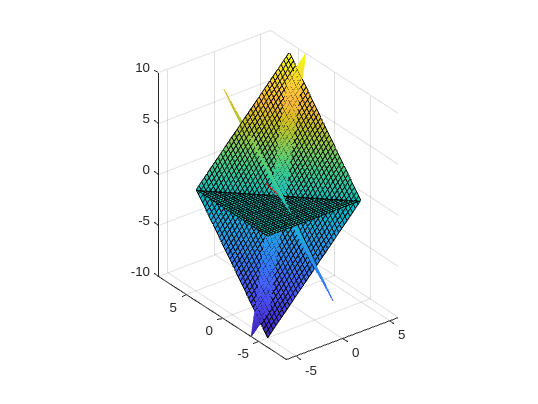

syms a b real; 
p=A([1 2], :)'*[a b]'; %Define p as: Matrix A, first two rows, and then all the columns, and the vector

fmesh(p(1),p(2),p(3),[-1 1]); axis equal;
N=null(A)*[-10 10];
line(N(1,:),N(2,:),N(3,:),'Color','r') ;

The vector obtined with the null space is orthogonal to the plane p we defined

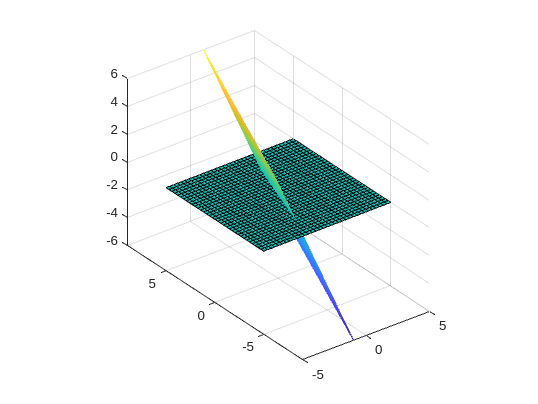

clf;
p=A([1 2],:)*[a b]'; %p defined as above.
q=S([1 2],:)*[a b]'; %q defined using the reduced echelon form matrix
fmesh(p(1),p(2),p(3),[-1 1]) 
axis equal; hold on;
fsurf(q(1),q(2),q(3),[-5 5]) 

%The same plane

## Left Null Space and Column Space

clf;
A=[1 0 1;5 4 9;2 4 6]; S=rref(A); %See above example
syms a b real;  p=A(:,[1 2])*[a b]'; %same as above
ezmesh(p(1),p(2),p(3)) %visualize the plane
axis equal; axis tight; hold on;
line(N(1,:),N(2,:),N(3,:),'Color','r') 
N=null(A')*[-10 10]; %The -10,10 is just two points of N for plotting the line
disp(N)

   -9.0453    9.0453
    3.0151   -3.0151
   -3.0151    3.0151



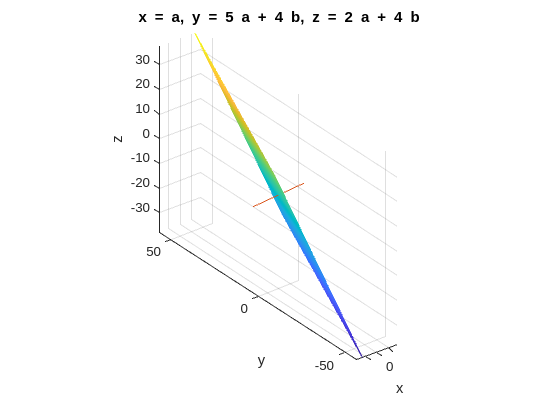

line(N(1,:),N(2,:),N(3,:)) %90° degree as above.

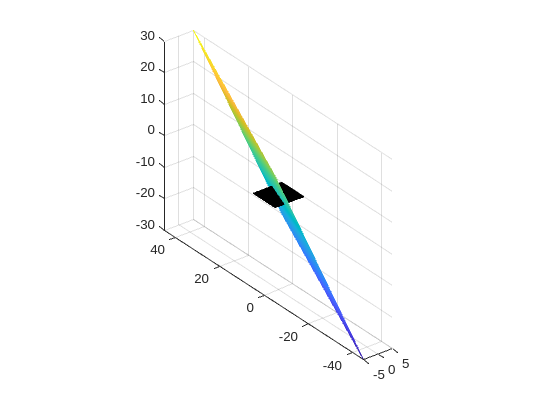


clf;
%--------- Ho sbaglito qualcosa qui
p=A(:,[1 2])*[a b]'; 
q=S(:,[1 2])*[a b]';
fmesh(p(1),p(2),p(3)); 
axis equal; hold on;
fsurf(q(1),q(2),q(3)); %Different planes!